# Waste Analysis Demo

Use the ThermoeconomicModel function to make waste analysis

### **Read and create the Thermoeconomic Model**

file="C:\Users\ctorr\Documents\Proyectos\TaesLab\Examples\rorc\rorc_model.json";
model=ThermoeconomicTool(file,'Debug',false);

### Define Waste Analysis Parameters

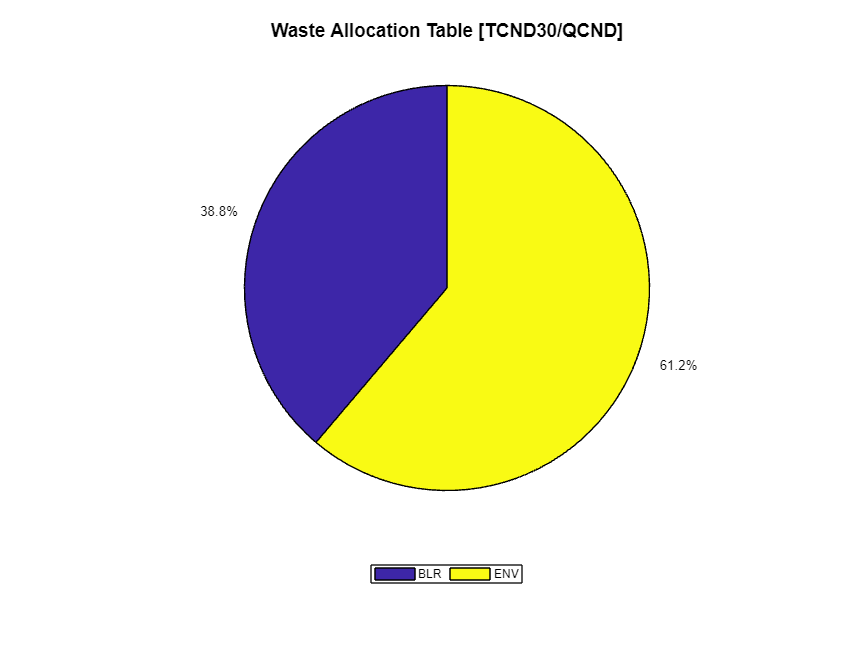

WasteFlows=convertCharsToStrings(model.WasteFlows);
model.ActiveWaste=convertStringsToChars(WasteFlows(1));
model.setWasteType(model.ActiveWaste,'HYBRID');
model.setWasteRecycled(model.ActiveWaste,0.6);
showGraph(model,cType.Tables.WASTE_ALLOCATION);

### Compute Exergy Cost and show results

printResults(model.wasteAnalysis)

Waste Definition Table

Key   Type     Recycling (%)
—————————————————————————————
QCND  HYBRID        60.00


Waste Allocation Table  (%)

 Key         QCND
——————————————————
 BLR        38.04
 TRB         0.25
 IHE         0.79
 PMP         0.92
 ENV        60.00


Direct Cost Recycling Analysis (J/J)

 Recycle (%)            WN       QCND
——————————————————————————————————————
      0             1.9906     1.5882
     10             1.9607     1.5645
     20             1.9317     1.5415
     30             1.9036     1.5192
     40             1.8762     1.4975
     50             1.8496     1.4764
     60             1.8238     1.4559
     70             1.7987     1.4360
     80             1.7742     1.4166
     90             1.7504     1.3977
    100             1.7272     1.3793



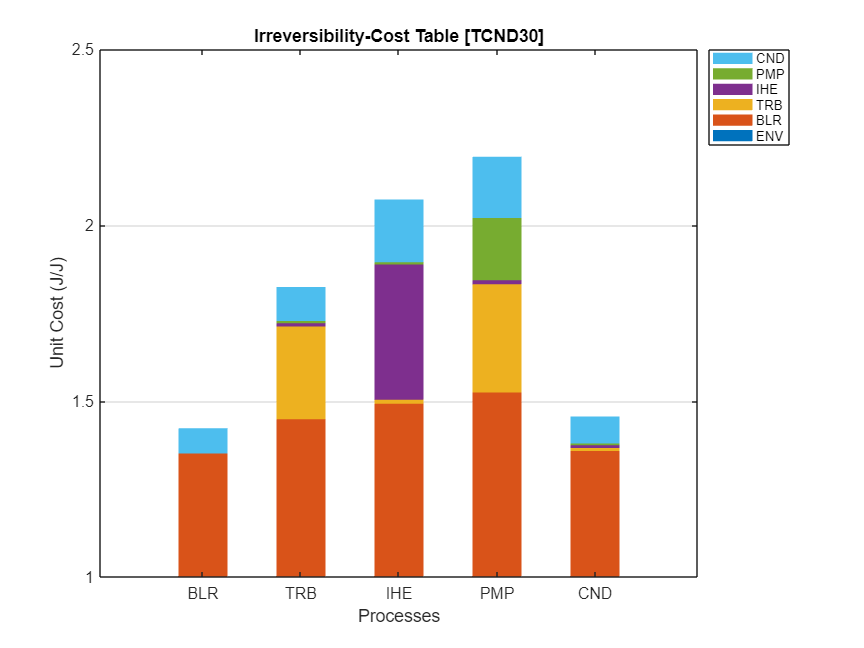

showGraph(model,cType.Tables.PROCESS_ICT);

### Recycling Analysis

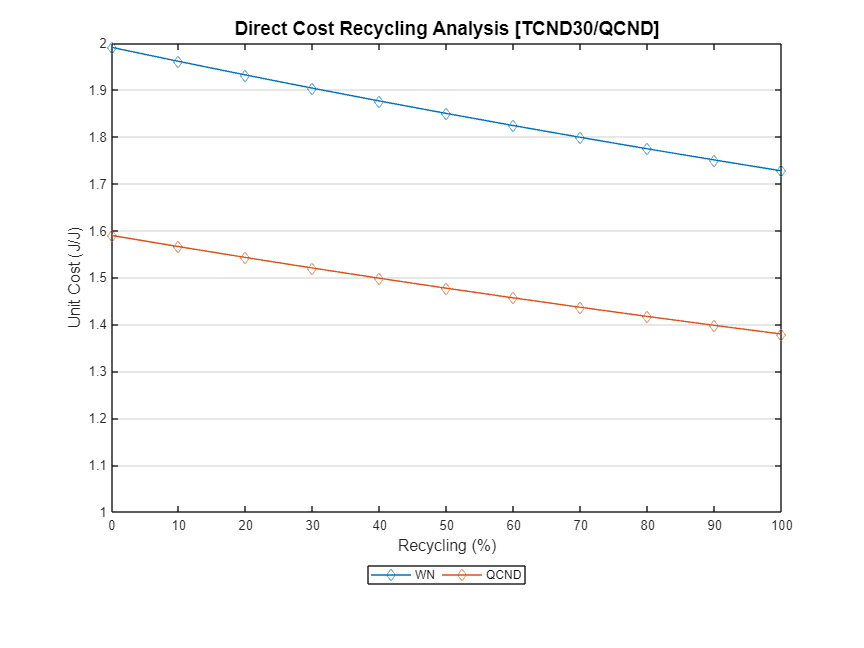

model.Recycling=true;
showGraph(model,cType.Tables.WASTE_RECYCLING_DIRECT);